First demo of matlab live script.

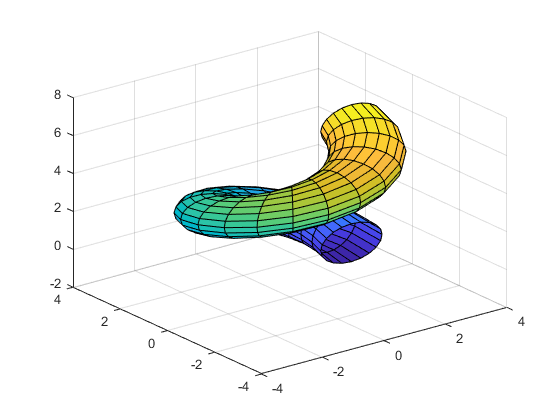

% parameter for the surface
[u,v] = meshgrid(0:pi/10:2*pi,0:pi/10:2*pi);

% surface definition
% paraboloid
x = (2 + sin(v)).*cos(u);
y = (2 + sin(v)).*sin(u);
z = u + cos(v);

% plotting commcand
surf(x,y,z)

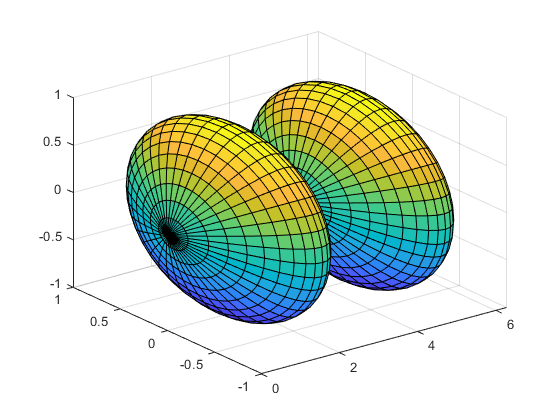

% parameter for the surface
[s,t] = meshgrid(0:pi/20:2*pi,0:pi/20:2*pi);

% surface definition
% paraboloid
x = s;
y = sin(s).*cos(t);
z = sin(s).*sin(t);

% plotting commcand
surf(x,y,z)

Area of a cylinder

% defining symbolic variables

syms u v
r = [2*cos(u), 2*sin(u), v]

$$r = \left(\begin{array}{ccc} 2\,\cos\left(u\right) & 2\,\sin\left(u\right) & v \end{array}\right)$$

ru = diff(r,u)

$$ru = \left(\begin{array}{ccc} -2\,\sin\left(u\right) & 2\,\cos\left(u\right) & 0 \end{array}\right)$$

rv = diff(r,v)

$$rv = \left(\begin{array}{ccc} 0 & 0 & 1 \end{array}\right)$$

c = cross(ru,rv)

$$c = \left(\begin{array}{ccc} 2\,\cos\left(u\right) & 2\,\sin\left(u\right) & 0 \end{array}\right)$$

nc = norm(c)  % length of vector

$$nc = \sqrt{4\,{\left|\cos\left(u\right)\right|}^{2}+4\,{\left|\sin\left(u\right)\right|}^{2}}$$

area = int(int(nc,u,0,2*pi), v,0,1)

$$area = 4\,\pi$$